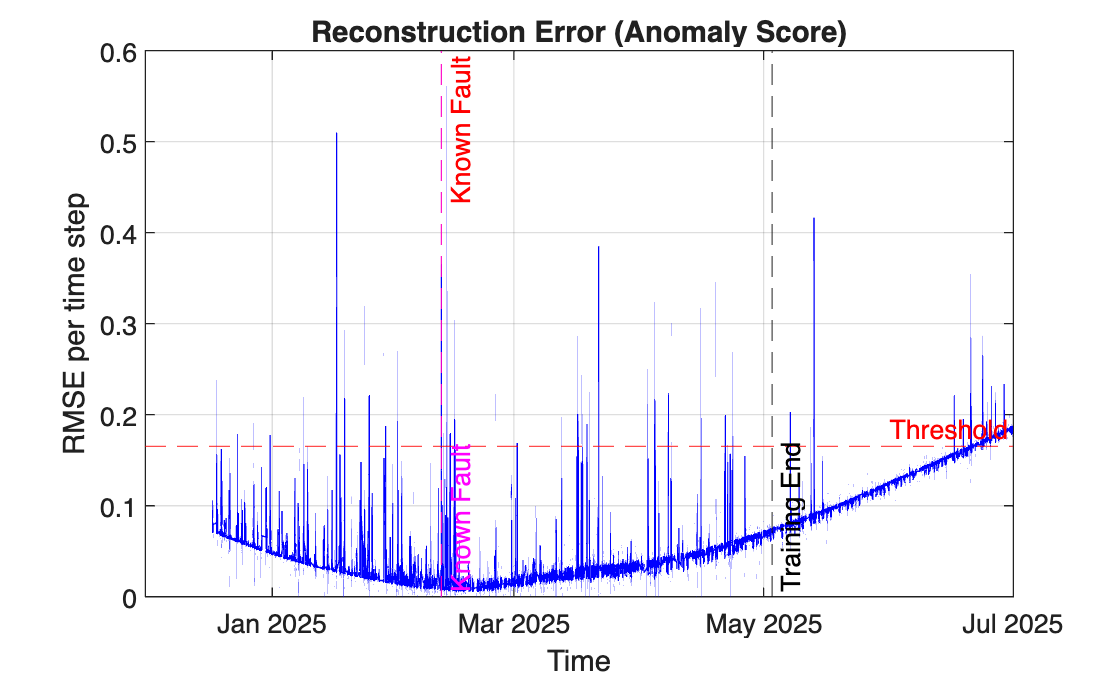

cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';  % replace with actual file
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');



numTrain = floor(0.7 * size(X, 1));

XTrain = {X(1:round(0.7 * end), :)'};  
Xseq   = {X'};                         


layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);


net = trainNetwork(XTrain, XTrain, layers, options);


Ypred = predict(net, Xseq);


reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  

timestamps = data.DateTime(end - numel(reconLoss) + 1:end);

figure;
plot(timestamps, reconLoss, 'b');
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
grid on;


xline(datetime('2025-02-11 07:33:05'), '--r', 'Known Fault')

 % Step 1: Identify training split point
trainEndIdx = round(0.7 * height(data));
trainEndTime = data.DateTime(trainEndIdx);


% Step 3: Plot threshold line (optional)
threshold = prctile(reconLoss, 95);
yline(threshold, '--r', 'Threshold');

% Step 4: Mark known fault
xline(datetime('2025-02-11 07:33:05'), '--m', 'Known Fault', 'LabelVerticalAlignment','bottom');

% Step 5: Mark end of training data
xline(trainEndTime, '--k', 'Training End', 'LabelVerticalAlignment','bottom');


% Step 6: Shade training and testing regions
yl = ylim;
fill([timestamps(1) trainEndTime trainEndTime timestamps(1)], ...
     [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.3);  % light gray

% Step 7: Final labels and legend
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
legend('Reconstruction Error', 'Threshold', 'Known Fault', 'Training End', 'Training Region', 'Location', 'northwest');

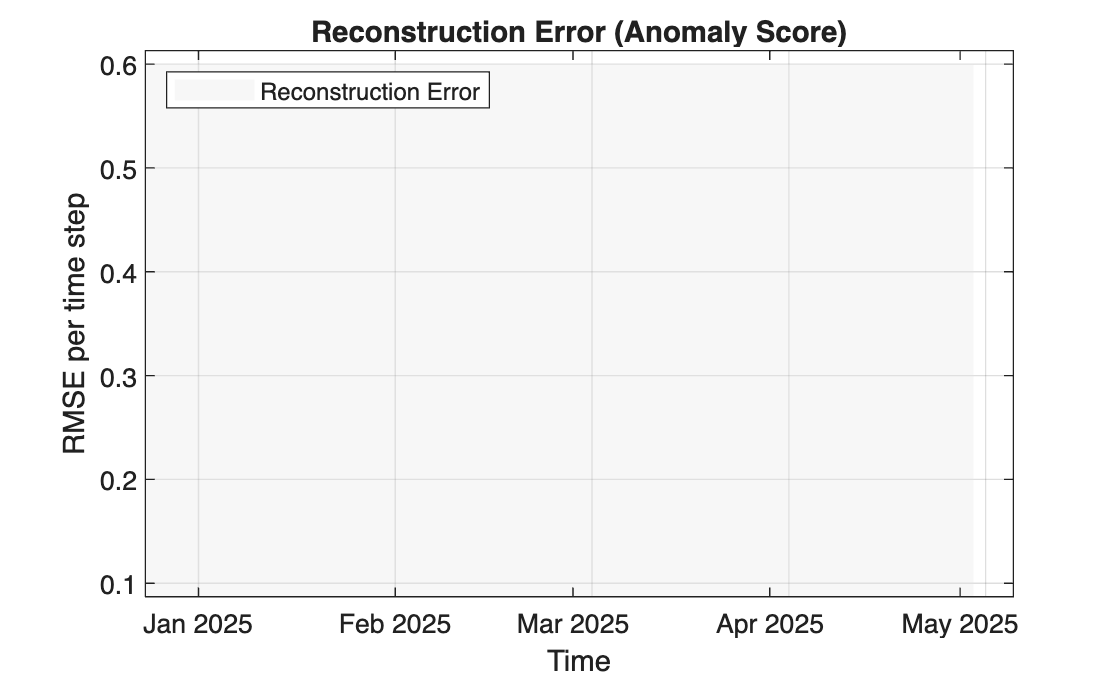

grid on;